# Tutorial05 Image processing and Analysis of Diffusing Molecules

#### Notes

Objective: Learn how to import images into Matlab and display them.

Will also dicuss about convolution, an IMPT operation in image analysis.

Fact: our eyes and brains are constantly doing convolutions whenever we look at anything.

Fact: Many kinds of lab data are presented as 2D arrays of #s 

=> They can conveniently be represented to our brains as images. 

E.g. atomic force measurement data, computed tomography data

Why is basic manipulation useful?

Because it helps us make images meaningful to humans.

2.. Images are Arrays of Numbers, aka Matrices.

**Fact**. Matlab can import and display images.

An image is just a 2D array of #s.

-> Therefore, we can take advantage of all of Matlab's fns to do calculations on the data that the image represent.

TO DO SO, we need to give Matlab access to some image data.

% load the image
A = imread('bwEmily.tiff');

If no semicolon, will get:

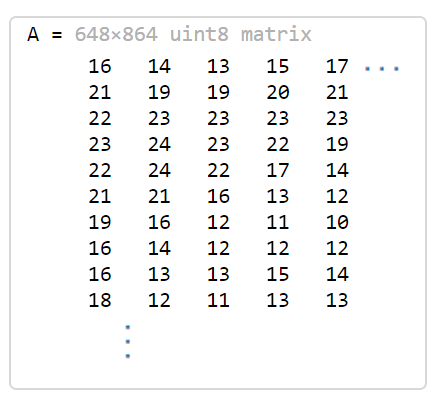

The array A arrives in a numeric format that Matlab finds inconvenient. So before proceeding, 

% convert the numeric format into a more usual form
A = single(A);

To view a black and white image, need to specify colourmap:

figure(1);
% specify colourmap
co = [0:255]/256;
colormap([co;co;co]');

(Notice the punctuation!) The **values of co** tell Matlab how brightly to illuminate each pixel for each allowed value in the image.

Note: The list appears three times in colormap because, for a grayscale image, we always want equal amounts of red, green, and blue 

Here, we've made a trivial (linear) choice; other choices would distort the image in interesting ways.

Having set the colourmap, use

% display the image
image(A);

3.. Convolution

Matlab defines the convolution C of an image I with a filter F as a new array of numbers:

where the ranges of the sums are over all values of k that refer to legal entries of both F and I. That is, all indices must be larger than zero and not larger than the size f their respective arrays.

4.. Averaging

The simplest filter we can choose assigns the same weight to each pixel in a fixed range. Make a 3x3 array F in which each element equals 1/9 

- Use the conv2 command to convolve the new filter with the image I downloaded and display the result.

n = 3
F1 = zeros(n,n);
a = 1/(n^2)
F1 = [a a a; a a a; a a a];

figure(2);
colormap([co;co;co]');

% convolve the new filter with the image
convolved_img1 = conv2(F1, A);
% display image
image(convolved_img1);

- Repeat the procedure with 15 x 15 array.

n = 15;
F2 = zeros(n,n);
a = 1/(n^2)'
F2(1:n, 1:n) = a;

figure(3);
colormap([co;co;co]');

% convolve the new filter with the image
convolved_img2 = conv2(F2, A);
% display image
image(convolved_img2);

% % Observation.
% The 15x15 image is a lot darker than 3x3.

-  Use the deﬁnition of convolution to show that the above procedure results in an image in which each pixel is the average of some of the neighboring pixels in the original.

Convolution(畳み込み): In mathematics  (in particular, functional analysis) convolution is a mathematical operation  on two functions  (f and g) that produces a third function expressing how the shape of one is modified by the other.

(関数  g を平行移動しながら関数 f に重ね足し合わせる二項演算である)

5.. Smooothing with a Gaussian

% load the image
load('gaussFilt.mat')
gauss
% help surf
% 3D colored surface.
figure(4);
surf(gauss);; title('The gaussian filter function')

convolved_gauss = conv2(gauss, A);
% display image
image(convolved_gauss);

- One pay prefer gauss over filter, because the filters created previously has the same elements in the matrix, whereas gauss is not.

6.. Denoising an Image

Measuring instruments (including our eyes!!) inevitably introduce some randomness, or "noise."

To simulate this, first make a noisy version of the original image by using rand.

% Create a noisy version of the original image
r = rand(1)
A_noise = r*A
image(A_noise);; title('Original image with noise')

% If a noisy image ended up being too dim.
% multiply r by smth bigger.
% e.g. r = (1.2)*rand(1)

with r = 0.9134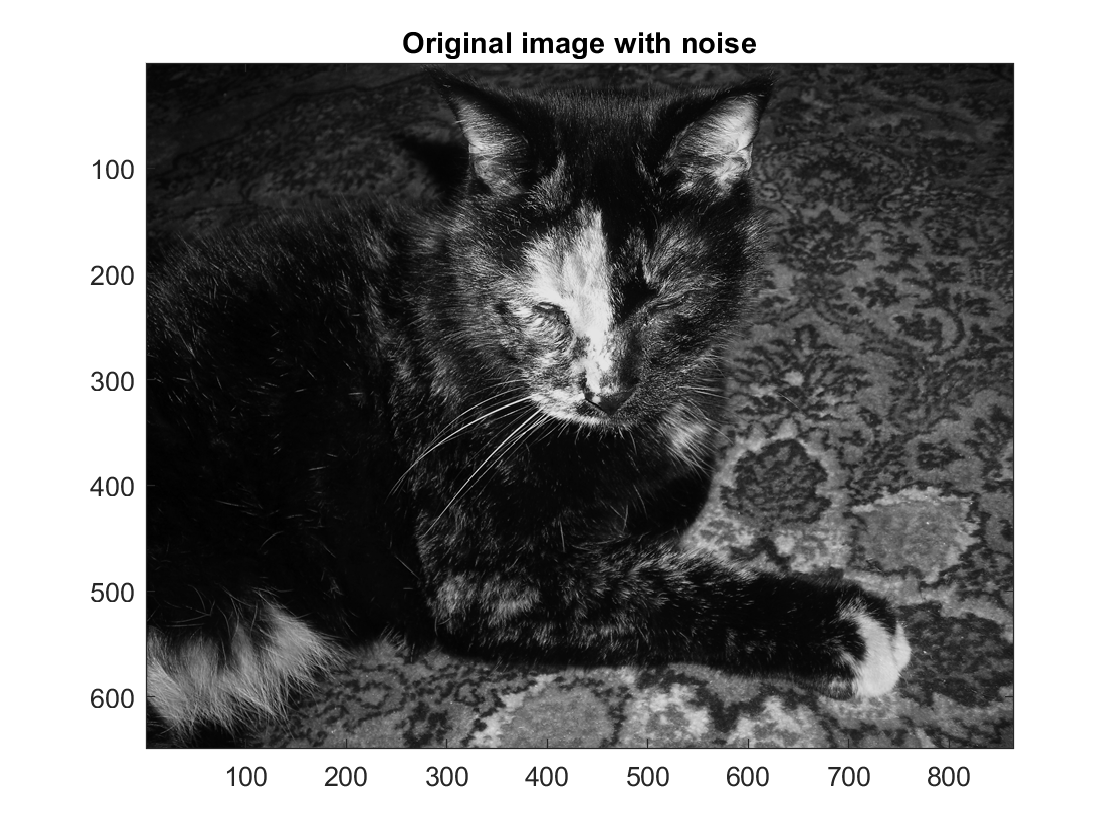

with r = 0.6324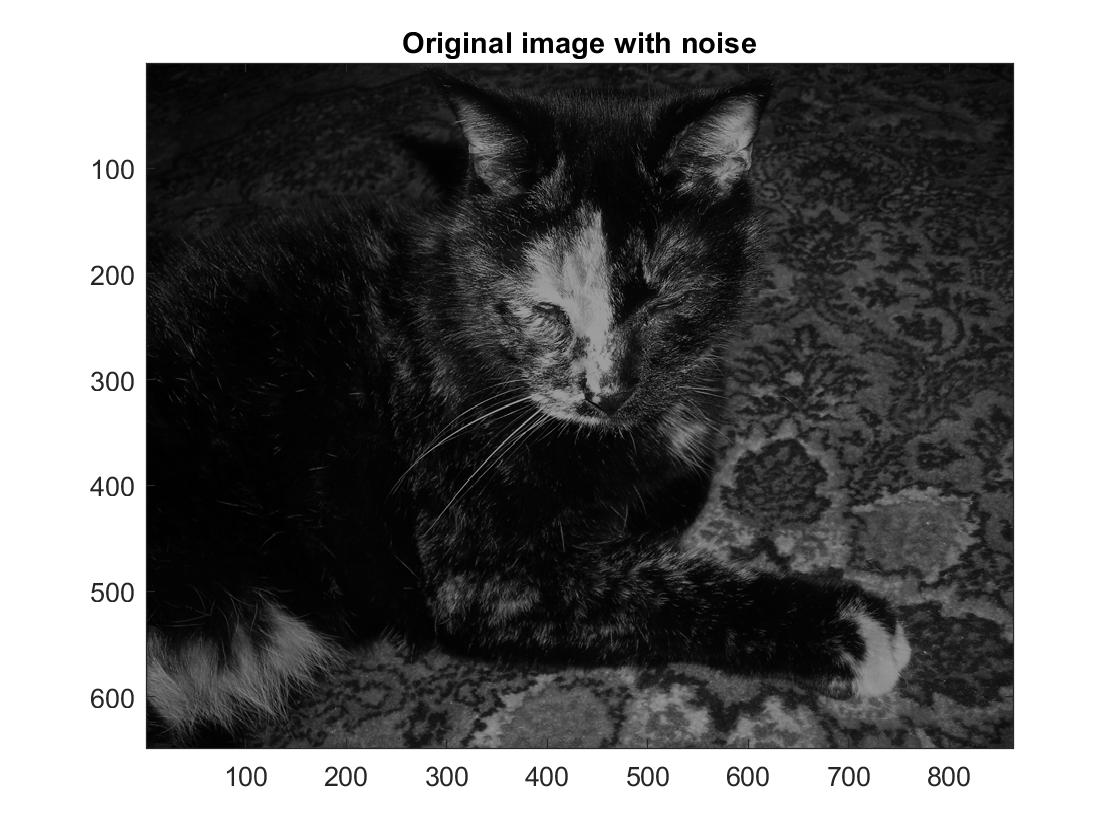

6.2 Suppressing Noise using Convolution.

- Apply Each of the three filters from the first part of the lab to the nosy img from #6. If they improve the pictures, explain why. Which one works the best? Why?

% colvolve a noisy image.
convolved_noisy_img1 = conv2(F1, A_noise);
convolvedconvolved_noisy_img2 = conv2(F1, A_noise);
convolved_noisy_gauss = conv2(gauss, A_noise);
% display image
image(convolved_noisy_img1);; title('noisy x filter 1')
image(convolvedconvolved_noisy_img2);; title('noisy x filter 2')
image(convolved_noisy_gauss);; title('noisy x gauss')

Filter 1 and 2 seemed to do better job than gauss. The image convoluted with gauss was (more) blurry.

8. Tasks (worked on then my notes and work were gone due to technical difficulties..)

Now, apply the general knowledge we've learned on how image processing works, and apply it to some specific tasks.

In previous part of this tutorial: We created our own masks and filtered with the convolution function.

FACT: Matlab has specific functions which supports a # of predetermined 2D linear spatial filters <- this way, we don't need to load in or create a function for a Gaussian each time etc.

**fspecial**: command to generate a mask

**imfilter**: command to comobine the mask with our image

1.. Fact: We can model the effect of the *motion blurring* as running temporal average (motion blurring of the fluorescence collected from rapidly diﬀusing molecules, when imaged onto a CCD camera).

We consider the particles as a model of freely diffusing molecules (the particles receive random kicks).

% Create a new matrix I_1(x, t) (from I(x, t), our old matrix of diffusing particles) for which a given value I_1(x, t)
% represents particle-# which has been time-averaged over a local time
% window duration h=5 time steps centered at time t.


%%% Getting the matrix I from tutorial04. Could have loaded them, I
%%% suppose, but decided to put in the code for refresh my memory.

% Parameters
L = 500
n_particle = 500
n_kicks = 10000

% initialization
f = zeros(n_kicks, n_particle);
x = zeros(n_kicks, n_particle);

f(1,:) = randperm(L)

% Assign kicks at each time step.
f(2:end,:) = randn(n_kicks-1, n_particle)

x = cumsum(f)
x = mod(x, 500)
x = ceil(x)  % ceil to discretize x.


%%% create image to store result.
I = zeros(L, n_kicks);
% for each number from 1 to 500, count the occurence and store in the matrix.
for n = 1:n_kicks
    location_ranges = 1:500;
    [counts, ind] = histc(x(n, :), location_ranges);
    I(:, n) = transpose(counts);  % can use " counts.' "
end

I
imshow(I)


% Create a new matrix I_1(x, t) (from I(x, t), our old matrix of diffusing particles) for which a given value I_1(x, t)
% represents particle-# which has been time-averaged over a local time
% window duration h=5 time steps centered at time t.


Choosing subsection of the matrix and showing it.

%figure
%I_section = I(:, 4500:5500,[])
% Correction comment: my initial range was 3:950, which was too wide.
imshow(I(:,4500:5500),[])

figure % create figure window
imshow(I(:,4500:5500),[]);
xlabel(['time']),ylabel(['position']) 